# 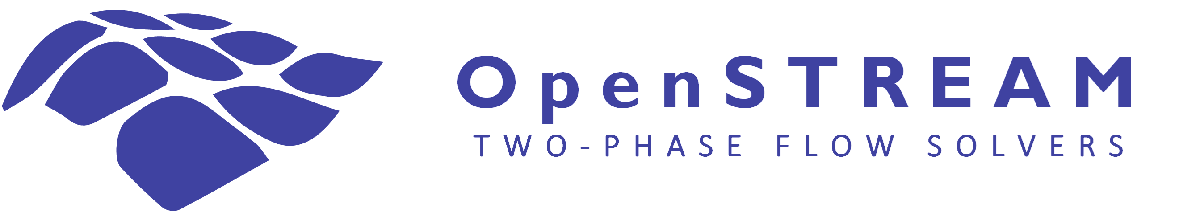

# Tutorial #8: Mesh and time-step sensitivity

This tutorial examines the sensitivity of OpenSTREAM results to spatial and temporal discretization. Steady-state solutions obtained with progressively refined axial meshes are compared, followed by a comparison of transient solutions calculated using different physical time steps. The mixture solver is used throughout the tutorial to demonstrate spatial- and temporal-discretization sensitivity studies. The same methodology can be applied to the two-fluid, three-field, and four-field solvers.

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter.

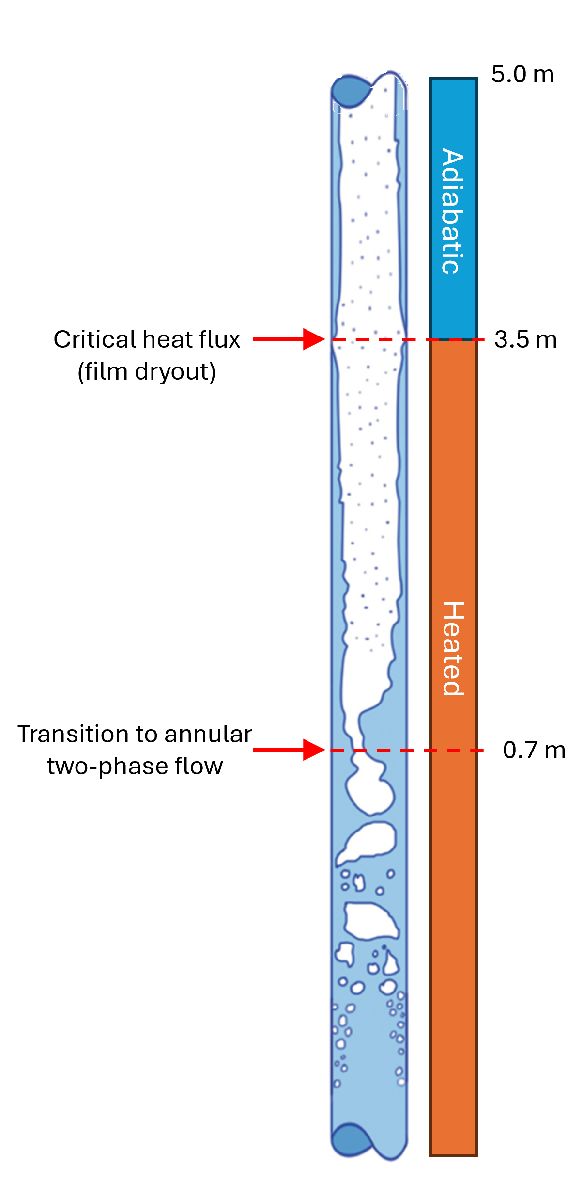

Learning objectives:

- Compare steady-state results obtained with progressively refined axial meshes.

- Compare transient responses obtained with different physical time steps.

- Identify quantities that are particularly sensitive to spatial or temporal resolution.

- Assess the tradeoff between numerical resolution, accuracy, and computational effort.

- Recognize when additional spatial or temporal refinement may be required.

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up OpenSTREAM

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

Import the inputs and solvers packages.

import Inputs.*
import Solvers.*
import Solvers.Mixture.*

## Spatial and temporal refinements

Display the physical-model input file and locate the TUTORIAL8 entries.

type('../inputs/models.inp')

Display the numerical-option input file and locate the DEFAULT and TUTORIAL8 entries.

type('../inputs/options.inp')

All cases use the same physical models, geometry, and operating conditions so that the effects of spatial and temporal discretization can be examined independently. The BESTION void-fraction model and the SAHAZUBER subcooled-boiling model are selected, and water is used as the working fluid. Model selections that are not explicitly specified retain their documented default values.

The spatial-refinement cases use progressively finer axial meshes:

- TUTORIAL8A uses 100 axial nodes.

- TUTORIAL8B uses 50 axial nodes.

- TUTORIAL8C uses 25 axial nodes.

These cases are used to examine how the axial mesh affects the converged steady-state solution.

The temporal-refinement study uses the TUTORIAL8B model set, which defines a 50-node mesh, together with three numerical-option sets:

- TUTORIAL8D uses a time step of 0.1 s.

- TUTORIAL8E uses a time step of 0.2 s.

- TUTORIAL8F uses a time step of 0.5 s.

These cases are used to examine how the physical time step affects the calculated transient response.

For both studies, only the discretization parameter being investigated is varied. The remaining physical models, geometry, boundary conditions, and applicable numerical settings are kept unchanged.

## Run the mesh study

Construct and solve the mixture solver for each axial mesh. All three calculations use the same physical models, numerical options, geometry, and boundary conditions. Only the number of axial nodes is changed.

The three meshes are:

- DEFAULT: fine mesh with 100 axial nodes;

- TUTORIAL8B: intermediate mesh with 50 axial nodes;

- TUTORIAL8C: coarse mesh with 25 axial nodes.

The 100-node solution is the finest tested spatial discretization and is used as the reference for this comparison. However, tt should not be interpreted as an exact or demonstrably mesh-independent solution.

### Fine mesh: 100 axial nodes

% Construct the input set.
warning off
inputSetA = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL8A', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
mixSolverA = MixtureSolver(inputSetA);
mixSolverA.solve();

### Intermediate mesh: 50 axial nodes

% Construct the input set.
warning off
inputSetB = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL8B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
mixSolverB = MixtureSolver(inputSetB);
mixSolverB.solve();

### Coarse mesh: 25 axial nodes

% Construct the input set.
warning off
inputSetC = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL8C', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
mixSolverC = MixtureSolver(inputSetC);
mixSolverC.solve();

All three calculations solve the same physical problem using different axial meshes. Any differences among the converged solutions therefore result from the spatial discretization, subject to the numerical convergence tolerances. The following section compares representative axial distributions qualitatively using the 100-node solution as the finest tested reference.

### Compare the mesh results

Plot the axial mass-flow-rate, vapor-quality, and void-fraction distributions for the three meshes.

% Plot the axial distributions for the fine mesh.
mixSolverA.plotz( ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% Plot the axial distributions for the intermediate mesh.
mixSolverB.plotz( ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% Plot the axial distributions for the coarse mesh.
mixSolverC.plotz( ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The three figures show the axial mass-flow-rate, vapor-mass-quality, and void-fraction distributions calculated using 100, 50, and 25 axial nodes. Comparing these distributions provides a qualitative assessment of the sensitivity of the steady-state solution to the spatial discretization.
For this case, the overall effect of mesh refinement is small. All three meshes produce similar axial profiles, amplitudes, and outlet values. The principal physical trends are therefore already captured by the 25-node mesh, and the calculated steady-state solution appears to be only weakly sensitive to further mesh refinement over the investigated range.
This limited sensitivity should not be interpreted as a general property of the solver. It reflects the relatively smooth axial behavior of this particular case and indicates that even the coarsest tested mesh provides sufficient resolution for the displayed quantities. Cases containing steep gradients, localized heat-flux changes, geometric perturbations, flow-regime transitions, or film dryout may exhibit stronger mesh sensitivity.
Increasing the number of nodes improves the resolution and visual smoothness of the calculated distributions. A coarse mesh may, however, smooth a localized variation, shift the apparent location of a transition, or fail to capture a local maximum or minimum between neighboring nodes. Consequently, mesh sensitivity should be assessed using both the overall axial distributions and quantities that may depend on local resolution, such as peak values and transition locations.

## Run the physical time-step study

Construct and solve the mixture solver for three physical time steps. All calculations use the same physical models, 50-node axial mesh, geometry, initial condition, and time-dependent boundary conditions. Only the physical time step, TSTEP, is varied.

The three time discretizations are:

- DEFAULT: fine time step of 0.1 s;

- TUTORIAL8E: intermediate time step of 0.2 s;

- TUTORIAL8F: coarse time step of 0.5 s.

The 0.1 s calculation will subsequently be used as the reference when comparing the transient results. This is the finest tested time discretization, but it should not be interpreted as an exact solution.

All three cases use the TUTORIAL8B physical-model set, which defines the common 50-node spatial mesh.

### Fine time step: 0.1 s

% Construct the input set.
warning off
inputSetD = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL8B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
mixSolverD = MixtureSolver(inputSetD);
mixSolverD.solve();

### Intermediate time step: 0.2 s

% Construct the input set.
warning off
inputSetE = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL8B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'TUTORIAL8E', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
mixSolverE = MixtureSolver(inputSetE);
mixSolverE.solve();

### Coarse time step: 0.5 s

% Construct the input set.
warning off
inputSetF = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL8B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'TUTORIAL8F', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
mixSolverF = MixtureSolver(inputSetF);
mixSolverF.solve();

All three calculations simulate the same physical transient using the same spatial mesh. Any differences among the calculated responses therefore result from the physical time discretization, subject to the numerical convergence tolerances. The following section compares the transient histories obtained using the three time steps.

### Compare the transient responses

Plot the physical-time evolution of the mass flow rates, vapor mass quality, and void fraction at the channel outlet for each time discretization.

% Plot the outlet response using the fine time step.
mixSolverD.plott( ...
    mixSolverD.NZ, ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% Plot the outlet response using the intermediate time step.
mixSolverE.plott( ...
    mixSolverE.NZ, ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% Plot the outlet response using the coarse time step.
mixSolverF.plott( ...
    mixSolverF.NZ, ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The three figures show the physical-time evolution of the selected quantities at the channel outlet using time steps of 0.1, 0.2, and 0.5 s. Comparing the curves provides a qualitative assessment of the sensitivity of the calculated transient response to the physical time discretization.
For this case, all three time steps reproduce the same overall transient behavior. Smooth and slowly varying parts of the response are captured reasonably well even with the coarsest time step. The principal differences occur during periods of rapid variation, particularly near peaks or abrupt changes in the mass flow rates.
The larger time steps provide fewer calculated states during these rapid changes. They may therefore smooth the transient response, underestimate or miss a local peak, and shift the calculated time at which an extremum occurs. The 0.1 s calculation provides the greatest temporal resolution and is used as the reference for this comparison.
The small observed differences in the slowly varying quantities should not be interpreted as evidence that the physical time step is unimportant in every calculation. Sensitivity may be stronger for faster boundary-condition changes, shorter-duration transients, rapidly propagating disturbances, or quantities governed by sharp temporal variations.
The time step should therefore be selected according to the shortest relevant time scale and the quantities of interest. A time step that adequately reproduces the general trend may still be too large for predicting peak values, peak timing, or short-duration behavior.

The mesh study showed limited sensitivity of the smooth steady-state distributions over the investigated mesh range. The time-step study similarly shows good agreement for slowly varying transient behavior but demonstrates that coarser temporal discretization can reduce the accuracy with which rapid changes and peak values are represented.

## Next steps

This tutorial provides an initial assessment of spatial- and temporal-discretization sensitivity. A more comprehensive study can extend the analysis in several ways:

- **Test additional mesh refinements.** Introduce finer axial meshes and compare their results with the 100-node solution. Successive refinement helps determine whether the calculated quantities approach a mesh-independent result.

- **Test additional time-step refinements.** Introduce physical time steps smaller than 0.1 s and compare the transient responses. This is particularly important when peak values, peak timing, or short-duration behavior are quantities of interest.

- **Quantify the differences.** Complement visual comparisons with numerical measures, such as maximum absolute differences, relative differences, outlet-value differences, and differences in the locations or timing of important events.

- **Compare complete spatial and temporal distributions.** Similar outlet values do not necessarily imply that the solutions are equivalent throughout the channel or over the complete transient. Local gradients, extrema, and transition locations should also be examined.

- **Perform a systematic convergence study. **Use several successively refined meshes or time steps to estimate the numerical convergence rate and, where appropriate, extrapolate toward a mesh- or time-step-independent solution.

- **Examine solver-specific quantities.** For the two-fluid, three-field, and four-field solvers, include phase or field velocities, enthalpies, film thickness, entrained-droplet flow, disturbance-wave quantities, and exchange terms, as applicable.

- **Investigate more demanding cases. **Repeat the study for problems containing stronger axial gradients, localized heat-flux changes, local pressure losses, flow-regime transitions, film dryout, or more rapid boundary-condition changes. Such cases may exhibit greater discretization sensitivity than the relatively smooth example considered here.

- **Evaluate computational effort. **Record the execution time, number of physical time steps, and convergence behavior for each discretization. The objective is to identify a mesh and time step that provide sufficient numerical accuracy without unnecessary computational cost.

- **Define study-specific acceptance criteria.** Determine acceptable differences based on the quantities of interest and the required numerical accuracy. Relative differences are useful for values sufficiently different from zero, while absolute differences are generally preferable for small values, peak timing, and transition locations.

The finest mesh and smallest time step used in a study should not automatically be treated as exact solutions. Confidence in numerical convergence increases when successive refinements produce progressively smaller changes in the quantities of interest.

## Summary

In this tutorial, you investigated the sensitivity of OpenSTREAM results to spatial and temporal discretization. The tested axial meshes produced similar steady-state distributions for this relatively smooth case, although finer meshes provided better resolution of local variations. The tested physical time steps reproduced the overall transient response, while the coarser time steps provided less accurate resolution of rapid changes and peak values. These comparisons demonstrate why mesh and time-step sensitivity should be assessed according to the quantities and physical time scales relevant to each study.